**Initial Setup**

The git link: https://github.com/DylShero/CaseStudies4

%Clear workspace
clear; clc; close all;

% Set grid parameter p 
p = 6;                  
n = 2^p - 1; %Number of interior grid points in 1D
N = n^2; %Total number of interior grid points

%Generate the matrix A
A = Poisson2D(n);

%Generate a random right-hand side f
rng(1); %Seed for RNG.
f = rand(N, 1);

## 1. Building the Multigrid Hierarchy

Before starting the solver, the first step is to construct the sequence of coarse grids. The Restrict function uses a full-weighting restriction operator to build the hierarchy of matrices A_list and restriction operators R_list. The coarsening stops when the system size falls below the specified threshold direct_N, at which point the system is solved directly.

%Threshold size to trigger the exact direct solve at the coarsest level
direct_N = 50; 

%Build the arrays of matrices and restriction operators
[A_list, R_list, max_level] = Restrict(A, direct_N);

fprintf('Hierarchy built with %d levels.\n', max_level);

Hierarchy built with 4 levels.


## 3. V-cycle Parameters and Initialization

The next step is to configure the solver parameters. The prolongation operator is defined linearly as P = 4R^T, hence our weight is 4. We use 2 steps of pre-smoothing and 2 steps of post-smoothing per level, applying the weighted-Jacobi method with a relaxation parameter of omega = 2/3. We start with a zero initial guess u0 = 0.

%Solver configuration
weight = 4; %Scaling factor for P (P = 4 * R')
pre_smooth = 2; %Number of pre-smoothing steps
pos_smooth = 2; %Number of post-smoothing steps
num_cycles = 15; %Total number of V-cycles to perform

%Initialize guess u^0 = 0 and an array to store residual norms
u = zeros(N, 1);
res_norms = zeros(num_cycles, 1);

## 4. Running the Multigrid Solver

The next step is iteratively applying the recursive Vcycle function. After each cycle, we compute the residual r^k = f - Au^k and calculate its Euclidean norm ||r||_2.

disp('Starting V-cycle iterations:');

Starting V-cycle iterations:


fprintf('Iter\t ||r||_2\n');

Iter	 ||r||_2



for k = 1:num_cycles
    %Apply one full Multigrid V-cycle starting at level 1
    u = Vcycle(1, A_list, R_list, f, u, direct_N, weight, pre_smooth, pos_smooth);
    
    %Compute the residual and store its Euclidean norm
    r_k = f - A * u;
    res_norms(k) = norm(r_k, 2);
    
    fprintf('%d\t %e\n', k, res_norms(k));
end

x =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


x =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


x =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


1	 3.530923e+00


x =     0.0003
    0.0005
    0.0007
    0.0008
    0.0010
    0.0011
    0.0013
    0.0014
    0.0015
    0.0016
    0.0017
    0.0018
    0.0019
    0.0020
    0.0020


x =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


x =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


2	 3.959880e-01


x =     0.0003
    0.0005
    0.0007
    0.0009
    0.0010
    0.0012
    0.0013
    0.0015
    0.0016
    0.0017
    0.0018
    0.0019
    0.0019
    0.0021
    0.0021


x =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


x =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


3	 6.086683e-02


x =     0.0003
    0.0005
    0.0007
    0.0009
    0.0011
    0.0012
    0.0013
    0.0015
    0.0016
    0.0017
    0.0018
    0.0019
    0.0020
    0.0021
    0.0021


x =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


x =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


4	 1.019280e-02


x =     0.0003
    0.0005
    0.0007
    0.0009
    0.0011
    0.0012
    0.0013
    0.0015
    0.0016
    0.0017
    0.0018
    0.0019
    0.0020
    0.0021
    0.0021


x =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


x =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


5	 1.776364e-03


x =     0.0003
    0.0005
    0.0007
    0.0009
    0.0011
    0.0012
    0.0013
    0.0015
    0.0016
    0.0017
    0.0018
    0.0019
    0.0020
    0.0021
    0.0021


x =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


x =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


6	 3.166194e-04


x =     0.0003
    0.0005
    0.0007
    0.0009
    0.0011
    0.0012
    0.0013
    0.0015
    0.0016
    0.0017
    0.0018
    0.0019
    0.0020
    0.0021
    0.0021


x =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


x =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


7	 5.723472e-05


x =     0.0003
    0.0005
    0.0007
    0.0009
    0.0011
    0.0012
    0.0013
    0.0015
    0.0016
    0.0017
    0.0018
    0.0019
    0.0020
    0.0021
    0.0021


x =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


x =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


8	 1.044698e-05


x =     0.0003
    0.0005
    0.0007
    0.0009
    0.0011
    0.0012
    0.0013
    0.0015
    0.0016
    0.0017
    0.0018
    0.0019
    0.0020
    0.0021
    0.0021


x =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


x =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


9	 1.920926e-06


x =     0.0003
    0.0005
    0.0007
    0.0009
    0.0011
    0.0012
    0.0013
    0.0015
    0.0016
    0.0017
    0.0018
    0.0019
    0.0020
    0.0021
    0.0021


x =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


x =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


10	 3.553505e-07


x =     0.0003
    0.0005
    0.0007
    0.0009
    0.0011
    0.0012
    0.0013
    0.0015
    0.0016
    0.0017
    0.0018
    0.0019
    0.0020
    0.0021
    0.0021


x =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


x =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


11	 6.608429e-08


x =     0.0003
    0.0005
    0.0007
    0.0009
    0.0011
    0.0012
    0.0013
    0.0015
    0.0016
    0.0017
    0.0018
    0.0019
    0.0020
    0.0021
    0.0021


x =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


x =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


12	 1.234838e-08


x =     0.0003
    0.0005
    0.0007
    0.0009
    0.0011
    0.0012
    0.0013
    0.0015
    0.0016
    0.0017
    0.0018
    0.0019
    0.0020
    0.0021
    0.0021


x =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


x =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


13	 2.317490e-09


x =     0.0003
    0.0005
    0.0007
    0.0009
    0.0011
    0.0012
    0.0013
    0.0015
    0.0016
    0.0017
    0.0018
    0.0019
    0.0020
    0.0021
    0.0021


x =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


x =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


14	 4.366646e-10


x =     0.0003
    0.0005
    0.0007
    0.0009
    0.0011
    0.0012
    0.0013
    0.0015
    0.0016
    0.0017
    0.0018
    0.0019
    0.0020
    0.0021
    0.0021


x =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


x =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


15	 8.260484e-11


## Convergence Analysis

The last step is to plot the residual norm ||r^k||_2 against the number of V-cycles k on a semi-logarithmic scale.

 The convergence plot shows linear convergence as shown by the sharply declining residual norm.

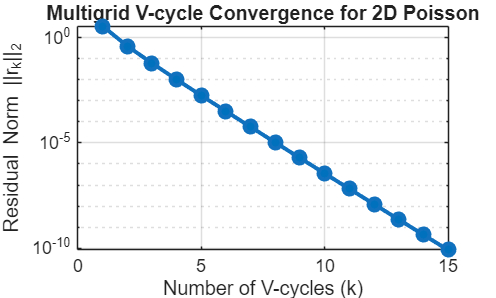

Average convergence factor: 0.195558


%Plot the convergence 
figure('Name', 'Multigrid Convergence');
semilogy(1:num_cycles, res_norms, '-o', 'LineWidth', 2, 'MarkerFaceColor', '#0072BD');
xlabel('Number of V-cycles (k)');
ylabel('Residual Norm ||r_k||_2');
title('Multigrid V-cycle Convergence for 2D Poisson');
grid on;